# **written for MATLAB R2022B**

# **IMAGES IMPORT**

**opens images (.fits files) by imread() and allows to trace loop by adding points with impixel(). you should select the last pixel with the ****right mouse button****.**

clear
close all
work_path = '/Users/nechaeva/Documents/MATLAB/oscillations_analysis';    % path to the folder with codes

cd(work_path)
load('sdoaia171.mat')

fold_path = '/Users/nechaeva/Documents/AIA_data/';    % your path to data files
date = '2023_07_19';    % date
loop_number = '01';    % change the number for different loops within one dataset

cd([fold_path date '_AIA_171'])    % path to .fits files

% mind that i have my files in the folder '/Users/nechaeva/Documents/AIA_data/2023_07_19_AIA_171'
% so it affects the code above ^

dirfiles = dir;
dirfiles(1:2) = [];    % removes system files (idk if you need this but i do)

for i = 1:size(dirfiles,1)
if (dirfiles(i).name(end-4:end) == '.fits' )    % choose only .fits file
    dirmat(i,1).name = dirfiles(i).name;
else
    dirmat(i,1).name = [];
end
end
dirfiles = dirmat;    % now all the names of .fits files is in dirfiles variable
clear dirmat i

m = round(size(dirfiles,1)/2);    % select image in the middle of timespane, you can set your own number


main_image = FITS.read(dirfiles(m).name,2);    % read .fits (sometimes 2 is needed if you don't alter fits)
main_image = flipud(main_image)*50;
sharpCoeff = [0 0 0;0 1 0;0 0 0]-fspecial('laplacian',0.2);
main_image_P = imfilter(main_image,sharpCoeff,'symmetric');

figure
    [xi,yi,P] = impixel(main_image_P);    % select points to trace
close
clear P

figure
    imshow(main_image_P);    % shows original image
    colormap(sdoaia171)
    th = text(14,30,'original image','Color','white','FontSize',12);

mkdir(['loop' loop_number])    % creates a folder for the analysed loop

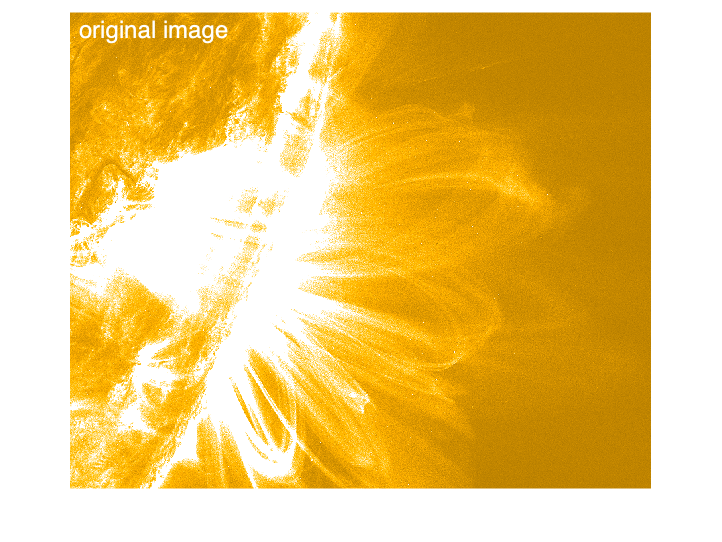


cd([fold_path date '_AIA_171' '/loop' loop_number])

saveas(gcf,'original_pic.png')    % saves the original pic

# **ANIMATE SEQUENCE OF IMAGES**

**uncomment if you need it. same rules as in the previous one**

% clear
% close all
% 
% work_path = '/Users/nechaeva/Documents/MATLAB/oscillations_analysis';    % path to the folder with codes
% cd(work_path)
% load('sdoaia171.mat')
% 
% fold_path = '/Users/nechaeva/Documents/AIA_data/';    % your path to data files
% 
% date = '2013_01_21';    % date
% cd([fold_path date '_AIA_171'])    % path to .fits files
% 
% % mind that i have my files in the folder '/Users/nechaeva/Documents/AIA_data/2023_07_19_AIA_171'
% % so it affects the code above ^
% 
% dirfiles = dir;
% dirfiles(1:3) = [];    % removes system files (idk if you need this but i do)
% 
% for i = 1:size(dirfiles,1)
% if (dirfiles(i).name(end-4:end) == '.fits' )    % choose only .fits file
%     dirmat(i,1).name = dirfiles(i).name;
% else
%     dirmat(i,1).name = [];
% end
% end
% dirfiles = dirmat;    % now all the names of .fits files is in dirfiles variable
% clear dirmat i
% 
% for m = 1:5:size(dirfiles,1)-1; % animate sequence
% 
%     main_image = FITS.read(dirfiles(m).name);    % read .fits
% 
%     pcolor(main_image)
%     colormap(sdoaia171)
%     clim([0 2000])
%     shading flat 
%     pause(0.001)
% end

**the code below shows image with selected pixels and fit them with different models.**

**i suggest to use elliptical fit of straight line****. splines are for experimentation with the appliance to other data.**

#### VERTICAL SPLINE

% figure
% imshow(main_image);
% hold on
% plot(xi,yi,'o','MarkerSize',6,'MarkerEdgeColor','k','MarkerFaceColor','w')
% 
% [xData,yData] = prepareCurveData(yi,-xi);
% ft = fittype('smoothingspline');
% opts = fitoptions('Method','SmoothingSpline');
% opts.SmoothingParam = 0.07;
%  
% [fitresult, gof] = fit(xData,yData,ft,opts);
% times = linspace(min(yi),max(yi),100);
% plot(-fitresult(times),times,'r','LineWidth',2)
% th = text(14,30,'vertical spline approximation','Color','white','FontSize',12);
% 
% clear gof ft th xData yData opts times

#### HORIZONTAL SPLINE

% % % figure
% % % imshow(main_image);
% % % hold on
% % % plot(xi,yi,'o','MarkerSize',6,'MarkerEdgeColor','k','MarkerFaceColor','w')
% % % 
% % % [xData,yData] = prepareCurveData(-xi,yi);
% % % ft = fittype('smoothingspline');
% % % opts = fitoptions('Method','SmoothingSpline');
% % % opts.SmoothingParam = 0.07;
% % %  
% % % [fitresult, gof] = fit(xData,yData,ft,opts);
% % % times = linspace(max(-xi),min(-xi),100);
% % % plot(-times,fitresult(times),'r','LineWidth',2)
% % % th = text(14,30,'horizontal spline approximation','Color','white','FontSize',12);
% % % 
% % % clear gof ft th xData yData opts times

# **ELLIPTICAL FIT**

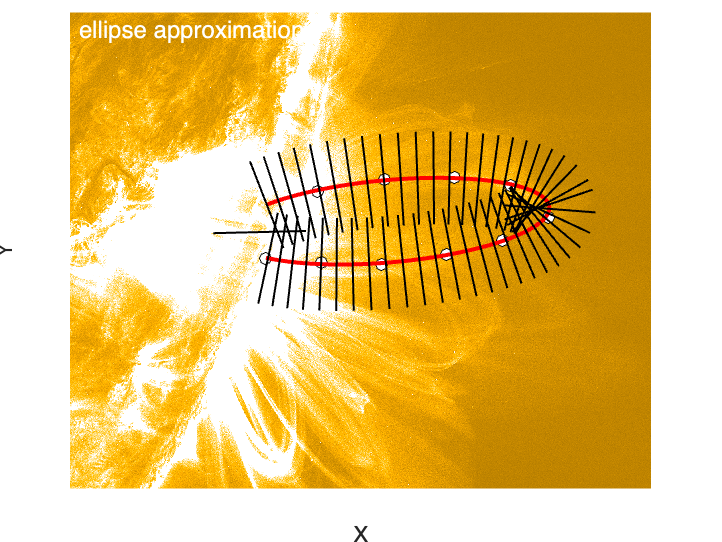

figure
    imshow(main_image_P);
    colormap(sdoaia171)
    hold on
    plot(xi,yi,'o','MarkerSize',6,'MarkerEdgeColor','k','MarkerFaceColor','w')

    th = text(14,30,'ellipse approximation','Color','white','FontSize',12);

xy = [xi,yi]';
fobj=ellipticalFit(xy);    % i use custom funtion https://www.mathworks.com/matlabcentral/fileexchange/87584-object-oriented-tools-for-fitting-conics-and-quadrics

    x_uns = 15;    % change based on the loop
    y_uns = 10;    % change based on the loop

[hFit,hData] = plot(fobj,{'LineWidth',2},{'Marker','none'}); 
hFit.XRange = [min(xi) max(xi)+x_uns];    
hFit.YRange = [min(yi)-y_uns max(yi)+y_uns];    % [min(yi)-y_uns max(yi)+y_uns] -- general form, 
                                                % you can change based on
                                                % your needs

s_ang = 3;    % angle sampling step size
d = 70;    % length of the slit
n = 1;    % number of slits between points DONT USE PLSSSS
sl = 2;   % slits step 

xyPost=fobj.sample(0:s_ang:360);
hold on
    hPost=scatter(xyPost{:},'filled','k','SizeData',10,'Marker','none');
hPost.XData(hPost.XData<min(xi)-x_uns) = NaN;
hPost.XData(hPost.XData>max(xi)+x_uns) = NaN;
hPost.YData(hPost.YData<min(yi)-y_uns) = NaN;
hPost.YData(hPost.YData>max(yi)+y_uns) = NaN;

Xi = hPost.XData(~isnan(hPost.XData) & ~isnan(hPost.YData));
Yi = hPost.YData(~isnan(hPost.XData) & ~isnan(hPost.YData));

n_sl = 1;
for i=1:sl:size(Xi,2)-1
    [xData, yData] = prepareCurveData(Xi(i:i+1),Yi(i:i+1));
    ft = fittype('poly1');
    [fitresult, gof] = fit(xData,yData,ft);    % fit y = kx + m
    coeffs = coeffvalues(fitresult);
    k1 = coeffs(1);    % k of orogonal line
    k2 = -1/k1;    % k of parallel line
    xx = (xData(2) - xData(1))/(n+1)*[1:n] + (xData(1));
    yy = (yData(2) - yData(1))/(n+1)*[1:n] + (yData(1));
    %plot(xx,yy,'b.','MarkerSize',10)

    X_dif = d/sqrt(k2^2+1);
    Y_dif = sqrt(d^2 - X_dif^2);

    
    
    if k2>0
        for j=1:n
                plot([xx(j)+X_dif xx(j)-X_dif],[yy(j)+Y_dif yy(j)-Y_dif],'k','LineWidth',1)
            sl_coord(:,:,n_sl) = (round([xx+X_dif xx-X_dif ; yy+Y_dif yy-Y_dif]));
            n_sl = n_sl+1;
        end
    else
        for j=1:n
                plot([xx(j)+X_dif xx(j)-X_dif],[yy(j)-Y_dif yy(j)+Y_dif],'k','LineWidth',1)
            sl_coord(:,:,n_sl) = (round([xx+X_dif xx-X_dif ; yy-Y_dif yy+Y_dif]));
            n_sl = n_sl+1;
        end
    end
end

save sl_coord.mat sl_coord    % saves both of the coodinates of slit endpoints
saveas(gcf,'ellipse_approx.png')    % saves image of the fit

# **STRAIGHT LINES**

% figure
%   imshow(main_image);
%   hold on
%   plot(xi,yi,'o','MarkerSize',6,'MarkerEdgeColor','k','MarkerFaceColor','w')
% 
%   plot(xi,yi,'r','LineWidth',2)
%   th = text(14,30,'straight lines approximation','Color','white','FontSize',12);
% 
% n = 2;    % number of slits between points
% d = 30;    % length of the slit
% 
% for i = 1:size(xi,1)-1
%     [xData, yData] = prepareCurveData(xi(i:i+1),yi(i:i+1));
%     ft = fittype('poly1');
%     [fitresult, gof] = fit(xData,yData,ft);    % fit y = kx + m
%     coeffs = coeffvalues(fitresult);
%     k1 = coeffs(1);    % k of orogonal line
%     k2 = -1/k1;    % k of parallel line
%     xx = (xData(2) - xData(1))/(n+1)*[1:n] + (xData(1));
%     yy = (yData(2) - yData(1))/(n+1)*[1:n] + (yData(1));
% 
%     X_dif = d/sqrt(k2^2+1);
%     Y_dif = sqrt(d^2 - X_dif^2);
%     
%     if k2>0
%         for j=1:n
%               plot([xx(j)+X_dif xx(j)-X_dif],[yy(j)+Y_dif yy(j)-Y_dif],'k','LineWidth',1)
%             sl_coord(:,:,n_sl) = (round([xx+X_dif xx-X_dif ; yy+Y_dif yy-Y_dif]));
%             n_sl = n_sl+1;
%         end
%     else
%         for j=1:n
%               plot([xx(j)+X_dif xx(j)-X_dif],[yy(j)-Y_dif yy(j)+Y_dif],'k','LineWidth',1)
%             sl_coord(:,:,n_sl) = (round([xx+X_dif xx-X_dif ; yy-Y_dif yy+Y_dif]));
%             n_sl = n_sl+1;
%         end
%     end
% end
% 
% clear gof ft th xData yData opts times 
